# Covariance 

Let's think we are simultaneously recording from two neurons in the visual cortex in response to some visual stimuli. One interesting thing to know is whether there is a relationship between neuronal response of these two neurons. 

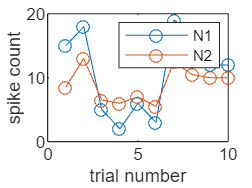

rng(2024)
N1 = randi(25,10,1); % spike counts of neuron 1 for 10 trials
N2 = .5*N1 + randi(5,10,1);

% plotting spike counts of two neuron over trials
figure
plot(N1,'o-')
hold on
plot(N2,'o-')
legend({'N1', 'N2'})

xlabel('trial number')
ylabel('spike count')

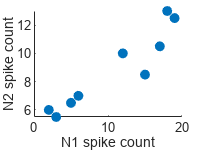


figure
scatter(N1,N2,'filled')
xlabel('N1 spike count')
ylabel('N2 spike count')

It seems that spike count of our neurons are related to each other. Let's start quantifying this relationship. For the beginning we can subtract mean of spike counts from each observed response to have sense wether the neuron is firing below or above in a trial, relative to its average activity.

meanSubN1 = N1 - mean(N1)

meanSubN1 =     4.1000
    7.1000
   -5.9000
   -8.9000
   -4.9000
   -7.9000
    8.1000
    6.1000
    1.1000
    1.1000


meanSubN2 = N2 - mean(N2)

meanSubN2 =    -0.4500
    4.0500
   -2.4500
   -2.9500
   -1.9500
   -3.4500
    3.5500
    1.5500
    1.0500
    1.0500


Some values are positive and some values are negative. What happens if negative values of N1 and N2 happen together and positive values also happen together? If this occurs then we can say our neurons are related to each other. To have sense of similarity between corresponding values we can compute dot product of mean subtracted values. When dot product is positive, it means that positive value happen together and negative values happen together in most case so dot product becomes positive. If positive values of one neuron happens with negative values of the other neuron the dot product becomes negative. So we have a measure to know wether our neurons' spike count are related or not. 

N1N2Dotproduct = dot(meanSubN1,meanSubN2)

N1N2Dotproduct = 144.9500

According to the value of the dot product there is a positive relationship between spike counts of N1 and N2, so when we can say when N1's spike count is high then we expect N2's spike count woud be also high.

This dot product of mean-subtracted measures is actually related to the concept of **covariance**, the only difference is in covariance we also normalize by the number of observations, in this case the number of trials.

Covariance formula:


$$\text{Cov}(X, Y) = \frac{1}{n} \sum_{i=1}^{n} (x_i - \bar{x})(y_i - \bar{y})
$$


or 


$$\text{Cov}(X, Y) = \frac{1}{n} (X - \bar{X})^T (Y - \bar{Y})
$$


When two variables have a positive covariance, it indicates that they tend to increase or decrease together. Conversely, a negative covariance suggests that as one variable increases, the other tends to decrease. A covariance of zero implies that there is no linear relationship between the variables.

# Correlation

However, covariance has a limitation in that its value is sensitive to the scale of measurement of the variables, making interpretation challenging. To solve this problem we can simply divide by the magnitude of the mean-subtracted observations vectors to make sure that value falls between -1 and +1 and we call it correlation coefficient.


$$\rho = \frac{x^T y}{\| x \| \| y \|}
$$


or 


$$\rho = \frac{\sum_{i=1}^{n} (x_i - \bar{x})(y_i - \bar{y})}{\sqrt{\sum_{i=1}^{n} (x_i - \bar{x})^2} \sqrt{\sum_{i=1}^{n} (y_i - \bar{y})^2}}
$$
